**Environment**

env = rlPredefinedEnv("BasicGridWorld")

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []


env.ResetFcn = @() 2

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: @()2


rng(0)

**Agent**

qTable = rlTable(getObservationInfo(env), getActionInfo(env))

qTable =   rlTable with properties:

    Table: [25×4 double]


qFcnAppx = rlQValueFunction(qTable,...
    getObservationInfo(env),...
    getActionInfo(env))

qFcnAppx =   rlQValueFunction with properties:

    ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
         ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
          UseDevice: "cpu"


qAgent = rlQAgent(qFcnAppx)

qAgent =   rlQAgent with properties:

            AgentOptions: [1×1 rl.option.rlQAgentOptions]
    UseExplorationPolicy: 0
         ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
              ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
              SampleTime: 1


qAgent.AgentOptions.EpsilonGreedyExploration.Epsilon = .04

qAgent =   rlQAgent with properties:

            AgentOptions: [1×1 rl.option.rlQAgentOptions]
    UseExplorationPolicy: 0
         ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
              ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
              SampleTime: 1


qAgent.AgentOptions.CriticOptimizerOptions.LearnRate = 0.01

qAgent =   rlQAgent with properties:

            AgentOptions: [1×1 rl.option.rlQAgentOptions]
    UseExplorationPolicy: 0
         ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
              ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
              SampleTime: 1


**Train**

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 50;
trainOpts.MaxEpisodes= 200;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 11;
trainOpts.ScoreAveragingWindowLength = 30;
trainingStats = train(qAgent,env,trainOpts);

**Valid**

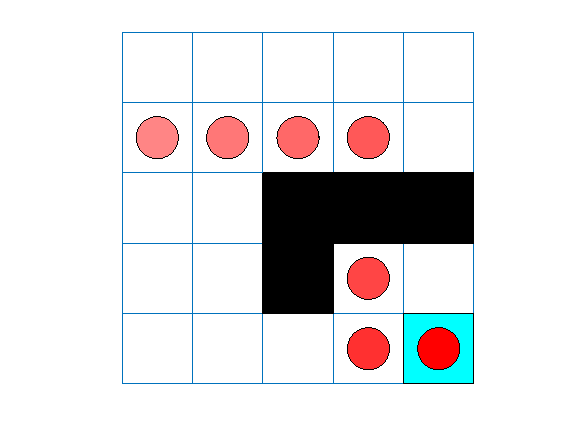

plot(env)
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;
sim(qAgent,env)